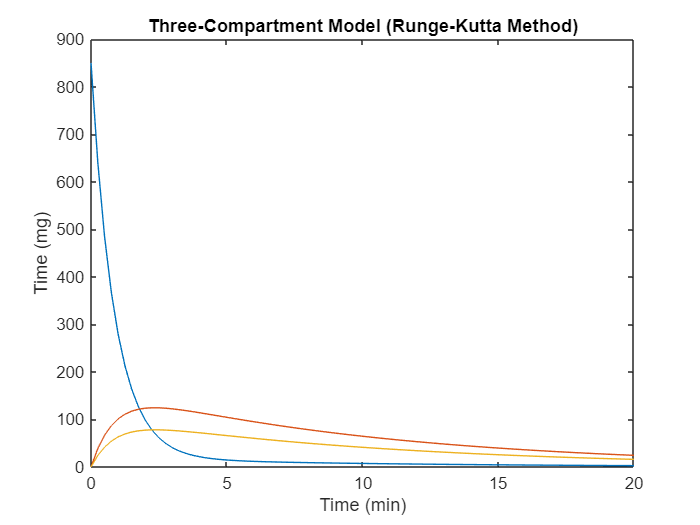

clc, clearvars, close all
syms A1(t) A2(t) A3(t) A4(t)

k20 = 55.8/60; %elimination 
k12 = 10.86/60;% central to liver
k21 = 6.96/60; % liver to central
k13 = 6.84/60; % central to healthy cells+tumour
k31 = 6.84/60; % healthy cells+tumour to central

%k14 = 0.1; % central to tumour
%k41 = 0.1; % tumour to central
C0 = 850; % mg
% half life is approx 7 mins
tf=20; %mins
%{
% 1 blood, 2 liver, 3 healthy cells and tumour
ode1 = diff(A1,t) == - k12 * A1 + k21 * A2 - k13 * A1 + k31 * A3; % - k14 * A1 + k41 * A4;
ode2 = diff(A2,t) == k12 * A1 - k21 * A2 - k20 * A2;
ode3 = diff(A3,t) == k13 * A1 - k31 * A3;
%ode4 = diff(A4, t) == k14 * A1 - k41 * A4;
odes = [ode1; ode2; ode3]; 

% initial conditions
cond1 = A1(0) == C0;
cond2 = A2(0) == 0;
cond3 = A3(0) == 0;
%cond4 = A4(0) == 0;
conds = [cond1; cond2; cond3];

% Compute Solutions
[A1Sol(t), A2Sol(t), A3Sol(t)] = dsolve(odes, conds);

% plot theoretical data
fplot(A1Sol,[0 tf]) 
hold on
fplot(A2Sol, [0 tf])
grid on
fplot(A3Sol, [0 tf])
%fplot(A4Sol, [0 tf])
legend("A1","A2", "A3", Location = "best");
title('Simulated Data of Three Compartment Model')
hold off
%}

% kutta runge method
h = 0.25;
ASol_Euler = zeros(tf+1,4);
% set initial conditions
ASol_Euler(1,1) = 0;
ASol_Euler(1,2) = C0;
ASol_Euler(1,3) = 0;
x=h; % x value incrementing by h
for i = 1:tf/h
    ASol_Euler(i+1, 1) = x;
    x = x + h;
    %Cent
    j1 = -k20 * ASol_Euler(i, 2) - k12 * ASol_Euler(i, 2) + k21 * ASol_Euler(i, 3);
    j2 = -k20 * (ASol_Euler(i, 2)+j1*h/2) - k12 * (ASol_Euler(i, 2)+j1*h/2) + k21 * (ASol_Euler(i, 3)+j1*h/2);
    j3 = -k20 * (ASol_Euler(i, 2)+j2*h/2) - k12 * (ASol_Euler(i, 2)+j2*h/2) + k21 * (ASol_Euler(i, 3)+j2*h/2);
    j4 = -k20 * (ASol_Euler(i, 2)+j3*h) - k12 * (ASol_Euler(i, 2)+j3*h) + k21 * (ASol_Euler(i, 3)+j3*h);
    ASol_Euler(i+1, 2) = ASol_Euler(i, 2) + h/6*(j1+2*j2+2*j3+j4);
    %Periph1
    j1 = k12 * ASol_Euler(i, 2) - k21 * ASol_Euler(i, 3);
    j2 = k12 * (ASol_Euler(i, 2)+j1*h/2) - k21 * (ASol_Euler(i, 3)+j1*h/2);
    j3 = k12 * (ASol_Euler(i, 2)+j2*h/2) - k21 * (ASol_Euler(i, 3)+j2*h/2);
    j4 = k12 * (ASol_Euler(i, 2)+j3*h) - k21 * (ASol_Euler(i, 3)+j3*h);
    ASol_Euler(i+1, 3) = ASol_Euler(i, 3) + h/6*(j1+2*j2+2*j3+j4);
    %Periph2
    j1 = k13 * ASol_Euler(i, 2) - k31 * ASol_Euler(i, 4);
    j2 = k13 * (ASol_Euler(i, 2)+j1*h/2) - k31 * (ASol_Euler(i, 4)+j1*h/2);
    j3 = k13 * (ASol_Euler(i, 2)+j2*h/2) - k31 * (ASol_Euler(i, 4)+j2*h/2);
    j4 = k13 * (ASol_Euler(i, 2)+j3*h) - k31 * (ASol_Euler(i, 4)+j3*h);
    ASol_Euler(i+1, 4) = ASol_Euler(i, 4) + h/6*(j1+2*j2+2*j3+j4);
end
%ode3 = diff(A3,t) == k13 * A1 - k31 * A3;

plot(ASol_Euler(:,1), ASol_Euler(:, 2))
hold on
plot(ASol_Euler(:,1), ASol_Euler(:, 3))
plot(ASol_Euler(:,1), ASol_Euler(:, 4))
title("Three-Compartment Model (Runge-Kutta Method)")
xlabel("Time (min)")
ylabel("Time (mg)")


ASol_Euler

ASol_Euler =          0  850.0000         0         0
    0.2500  640.9926   38.7767   24.2250
    0.5000  484.3738   66.8849   41.8029
    0.7500  366.9877   87.0263   54.4161
    1.0000  278.9830  101.2238   63.3244
    1.2500  212.9824  110.9914   69.4707
    1.5000  163.4614  117.4626   73.5608
    1.7500  126.2834  121.4854   76.1230
    2.0000   98.3504  123.6945   77.5525
    2.2500   77.3426  124.5648   78.1453


%{
tiledlayout(2,2)
nexttile
fplot(A1Sol,[0 tf]) 
title('Blood Plasma (Central)')
nexttile
fplot(A2Sol, [0 tf])
title('Liver (Perph1)')
nexttile
fplot(A3Sol, [0 tf])
title('Healthy Cells (Perph2)')
hold off
%{
nexttile
fplot(A4Sol, [0 tf])
title('Tumour (Perph4)')
%}
%48 hour, every half hour measurement
x_A = linspace(0, tf, tf+1)
y_A = zeros(tf+1, 3)
for i = 0:tf
    y_A(i+1,1) = A1Sol(i);
    y_A(i+1,2) = A2Sol(i);
    y_A(i+1,3) = A3Sol(i);
end
figure
y_A
scatter(x_A, y_A)
%80
%}